mdl = "linear_Einspurmodel";
load_system(mdl)

t = (0:0.01:10)';                 
u = 5 * ones(size(t));   % Sprung

u_ext = [t u];                    % [time  input]
v = 18

v = 18

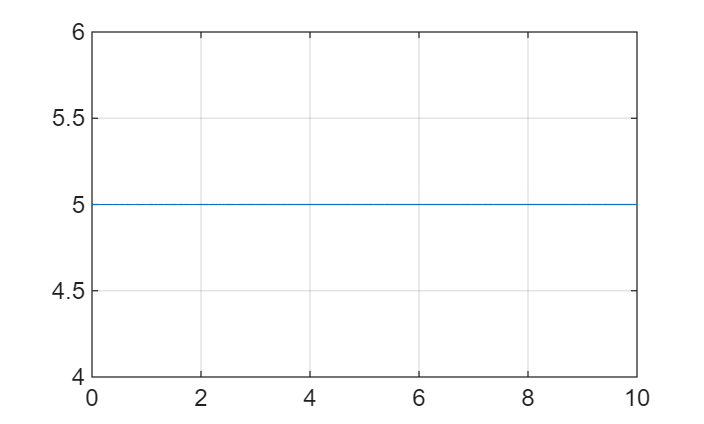


set_param(mdl,'LoadExternalInput','on');
set_param(mdl,'ExternalInput','u_ext');
simOut = sim(mdl,'StopTime','10');

beta_ts   = simOut.logsout.getElement('beta').Values;
delta_ts = simOut.logsout.getElement('delta_in').Values;
plot(delta_ts.Time, delta_ts.Data); grid on

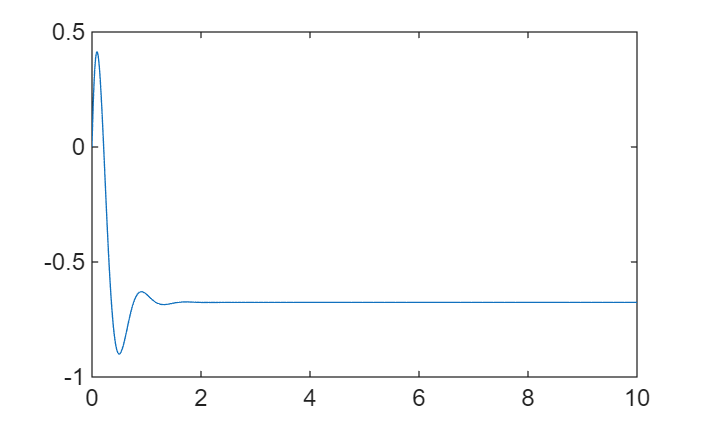

plot(beta_ts.Time, beta_ts.Data)